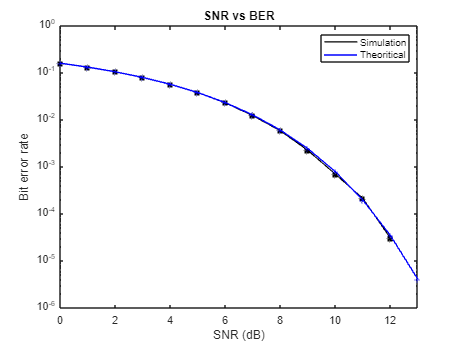

clc;
clear;
close;

SNR_dB = 0:1:40;                      % SNR
SNR = 10.^(SNR_dB/10);

N = 10^6; 
m_str = randi([0 1],1,N);             % message samples

% BPSK signals
% our signal space is one dimensional and signal vector we get is of the form si = {+sqrtE, -sqrtE}
% so to generate our bpsk signals we will use a polar NRZ scheme where bit 0 --> +1 and bit 1 --> -1

s_bpsk = 1 - 2*m_str;

% AWGN channel
% the noise is assumed to be additive white gaussian with zero mean and power spectral density is N0/2. 

noise = randn(1,N);                     % for our example we assume the noise is N(0,1) such that noise power  = 1

% Transmitting our bpsk signals over the AWGN channel

for i=1:length(SNR)                     % we iterate for different SNR values

    x = sqrt(SNR(i)) * s_bpsk + noise;  % recieved signal 
    
    % we will keep a threshold of zero as we are using a maximum likelihood
    % detector which in our case the threshold will be the perpendicular bisector between our points.
    % i.e if x < 0 => bit 1 and if x > 0 => bit 0
    
    % we need to identify the bits that will be wrongly predicted due to
    % the noise addition. To do this we need to identify which bits have a
    % change in energy due to noise.
    
    error_bits = x.* s_bpsk;
    ind_error_bits = find(error_bits < 0); 
    no_of_error_bits(i) = length(ind_error_bits);
    
end

ber = no_of_error_bits/N;              % BER (simulation)

% BER (theoritical)

ber_theo = qfunc(sqrt(SNR));           % the BER theoritically is Q(sqrt(2E/No))

figure()
plt_ber_sim = semilogy(SNR_dB, ber, 'k*-', 'LineWidth',1);     % plotting the SNR vs BER 
hold on;

plt_ber_theo = semilogy(SNR_dB, ber_theo, 'b+-');

xlabel("SNR (dB)");
ylabel("Bit error rate");
xlim([0 13]);
legend([plt_ber_sim plt_ber_theo], {'Simulation','Theoritical'});
title('SNR vs BER');